# Examples for using the `fixed_point_iteration` function.

Copyright © 2021 Tamas Kis

## Example #1: Fixed point of a simple function.

*Find the fixed point of *$f\left(x\right)=\sqrt{x}$.

Defining $f\left(x\right)$,

f = @(x) sqrt(x);

To demonstrate the fact that, for this specific function, the fixed point iteration can converge even with an initial guess very far from the true fixed point, we use an initial guess of $x_0 ={10}^{10}$ 

c = fixed_point_iteration(f,10^10)

c = 1.0000

## Example #2: Plot of fixed point estimates at each iteration.

*In Example #1, we found the fixed point of *$f\left(x\right)=\sqrt{x}$* using fixed point iteration with an initial guess of *$x_0 ={10}^{10}$*. Now, produce a plot of all fixed point estimates obtained by the *`fixed_point_iteration`* function during its solution procedure, this time using an initial guess of *$x_0 =100$.

First, we define $f\left(x\right)$ in MATLAB like before.

f = @(x) sqrt(x);

To obtain the fixed point estimates at all iterations, we simply need to define the `opts` structure, set its `return_all` field to `true`, and pass it to the `fixed_point_iteration` function. *(Note: we use the same initial guess as in Example #1).*

opts.return_all = true;
[~,~,c_all] = fixed_point_iteration(f,100,opts);

Plotting the fixed point estimates at each iteration,

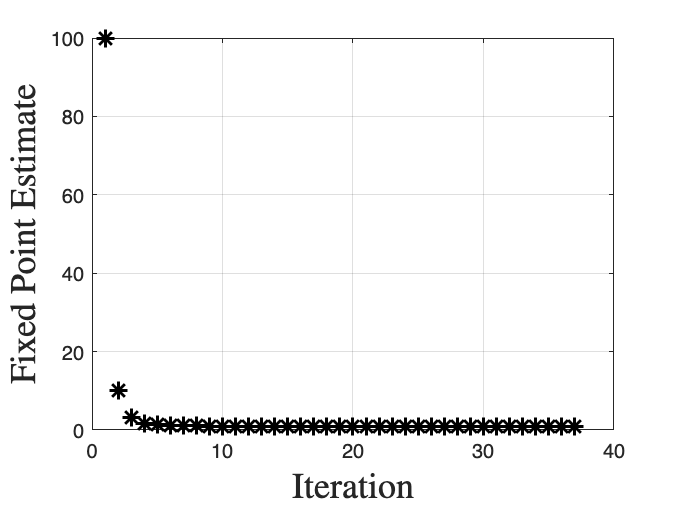

figure;
plot(c_all,'k*','MarkerSize',9,'LineWidth',1.5);
grid on;
xlabel('Iteration','Interpreter','latex','FontSize',18);
ylabel('Fixed Point Estimate','Interpreter','latex','FontSize',18);

## Example #3: Root-finding via fixed-point iteration.

*Use fixed-point iteration to find the root of *$f\left(x\right)=x^2 -1$ in the interval $\left\lbrack 0,\infty \right)$.

Finding a root of $f\left(x\right)$ is equivalent to finding a fixed point of $g\left(x\right)=x-f\left(x\right)$. Therefore, we define

                    
$$g\left(x\right)=x-f\left(x\right)=x-\left(x^2 -1\right)$$


                    
$$g\left(x\right)=-x^2 +x+1$$


Defining $g\left(x\right)$ in MATLAB,

g = @(x) -x^2+x+1;

Since we want the positive root of $f\left(x\right)=x^2 -1$, we pick an initial guess $x_0 =1\ldotp 9$. Finding the positive root of $f\left(x\right)$ by finding the fixed point of $g\left(x\right)$,

root = fixed_point_iteration(g,1.9)

root = 1.0475

While we obtain a result close to the true result of 1, the fixed-point iteration never converges to within the default tolerance ($\textrm{TOL}={10}^{-10}$).

## Example #4a: Pipe flow problem (simple solution).

*Consider a pipe flow problem where the velocity of the fluid, *$V$*, is a function of the friction factor, *$f$*.*

                    
$$V=\sqrt{\frac{3000}{700f+10}}\;\textrm{ft}/\mathrm{s}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


*The Reynolds number, *$\textrm{Re}$*, is dependent on the velocity as*

                    
$$\textrm{Re}=600000V\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$


*Finally, *$f$* is a function of *$\textrm{Re}$* (assuming a smooth pipe).*

                    
$$\frac{1}{\sqrt{f}}=-1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{\textrm{Re}}\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)$$


*Find the velocity of the flow through the pipe.*

Let's begin by solving Eq. (3) for $f$.

                    
$$f={\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{\textrm{Re}}\right)\right\rbrack }^{-2} \;\;\;\;\;\;\;\;\;\;\;\left(4\right)$$


Equations (1), (2), and (4) must be satisfied simultaneously. While we have three equations in three unknowns, we cannot solve this system of equations algebraically due to the nonlinearities in the equations for $V$ and $f^{-1/2}$. However, note that we can form a calculation procedure that maps $V$ to itself:

- From Eq. (1), we can get $V$ from $f$.

- From Eq. (3), we can get $f$ from $\textrm{Re}$.

- From Eq. (2), we can get $\textrm{Re}$ from $V$

This calculation procedure essentially gives us a function $V=g\left(V\right)$:

                    
$$g:V\to \textrm{Re}\to f\to V$$


Therefore, the flow velocity $V$ is simply the fixed point of $g\left(V\right)$ (since $g$ maps $V$ to itself).

We *could* use function composition to define $g\left(V\right)$ using a single expression (in fact, this is exactly what we do in Example #4b below). However, it is quicker/easier to define a *computational* function that evaluates $g\left(V\right)$ in a *sequential *fashion. **We define **$g\left(V\right)$** as the MATLAB function gV at the bottom of this page under the "**`gV`** Function for Example #4a" section.** To define $g\left(V\right)$ as an anonymous function, we assign it a function handle:

g = @(V) gV(V);

Solving for $V$ using an initial guess of $V_0 =1\;\textrm{ft}/\mathrm{s}$,

V = fixed_point_iteration(g,1)

V = 13.7583

## Example #4b: Pipe flow problem (long solution).

*Consider a pipe flow problem where the velocity of the fluid, *$V$*, is a function of the friction factor, *$f$*.*

                    
$$V=\sqrt{\frac{3000}{700f+10}}\;\textrm{ft}/\mathrm{s}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


*The Reynolds number, *$\textrm{Re}$*, is dependent on the velocity as*

                    
$$\textrm{Re}=600000V\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$


*Finally, *$f$* is a function of *$\textrm{Re}$* (assuming a smooth pipe).*

                    
$$\frac{1}{\sqrt{f}}=-1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{\textrm{Re}}\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)$$


*Find the velocity of the flow through the pipe.*

While we have three equations in three unknowns, we cannot solve this system of equations algebraically due to the nonlinearities in the equations for $V$ and $f^{-1/2}$. Let's begin by solving Eq. (3) for $f$.

                    
$$f={\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{\textrm{Re}}\right)\right\rbrack }^{-2} \;\;\;\;\;\;\;\;\;\;\;\left(4\right)$$


Now, we can think of Eqs. (1), (2), and (4) in the following way:

                    
$$V=\phi_1 \left(f\right)$$


                    
$$\textrm{Re}=\phi_2 \left(V\right)$$


                    
$$f=\phi_3 \left(\textrm{Re}\right)$$


We know we can use fixed-point iteration to find the fixed point $x=c$ of a function $f\left(x\right)$ (i.e. $f\left(c\right)=c$). Therefore, our goal is to develop a function where both the input and output are $V$. Then, we can use fixed-point iteration to solve for $V$. Since we can get $V$ from $f$, get $f$ from $\textrm{Re}$, and get $\textrm{Re}$ from $V$ (i.e. $V\to \textrm{Re}\to f\to V$), we can determine such a function using function composition:


$$V=\phi_1 \left(\phi_3 \left(\phi_2 \left(V\right)\right)\right)$$


Mathematically, this involves substituting Eq. (2) into Eq. (4), and then substituting the result into Eq. (1).

                    
$$f={\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{600000V}\right)\right\rbrack }^{-2} \;\;\;\;\to \;\;\;V=\sqrt{\frac{3000}{700{\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{600000V}\right)\right\rbrack }^{-2} +10}}$$


Now, let's define the function $g\left(V\right)$ as the right hand side of the equation above for $V$.

                    
$$g\left(V\right)=\sqrt{\frac{3000}{700{\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{600000V}\right)\right\rbrack }^{-2} +10}}$$


Since we have essentially let $g\left(V\right)=V$, the velocity of the flow through the pipe, $V$, is simply the fixed point of $g\left(V\right)$. Defining $g\left(V\right)$ in MATLAB,

g = @(V) sqrt(3000/(700*(-1.8*log10(6.9/(600000*V)))^(-2)+10));

Obtaining the flow velocity by finding the fixed point of $g\left(V\right)$, using an initial guess of $V_0 =1\;\textrm{ft}/\mathrm{s}$,

V = fixed_point_iteration(g,1)

V = 13.7583

*Clearly, this method is more difficult than that presented in Example #4a, even for such a simple problem. *

## `gV` Function for Example #4a

function V = gV(V)
    Re = 600000*V;
    f = (-1.8*log10(6.9./Re)).^(-2);
    V = sqrt(3000./(700*f+10));
end